# Stability-Based Analysis of Velocity Spectra from FINO1

## Introduction

This script loads preprocessed sonic anemometer data from the FINO1 offshore platform and classifies it by atmospheric stability using the Monin–Obukhov parameter η= z/L�

where z is the measurement height and L is the Obukhov length.

We then compute normalized velocity variances and perform spectral fitting for each component of the velocity field (u,v,w) and the Reynolds shear stress (u′w′).

The present script uses a slightly different data processing than used in **Cheynet, E., Bogunovic Jakobsen, J., & Reuder, J. (2018).***Velocity spectra and coherence estimates in the marine atmospheric boundary layer*.Boundary-Layer Meteorology, 169, 429–460. DOI: 10.1007/s10546-018-0382-2 [Accepted version on NORA](https://hdl.handle.net/11250/3040299)

The velocity spectra were estimated using Wlech's method, three segments and 50% overlapping whereas in the paper, the single segments were used.

`Wind`** Structure – Key Fields Explained**

- `time`→ Time vector corresponding to starting time of the time series (in MATLAB `datenum` format)

- `z`→ Measurement heights above sea level [80, 60, 40] m

- `Nsamples`→ Number of samples, e.g. 720 means 720 time series of 60 min were used

- `U`→ Mean horizontal wind speed at each height, computed as $U=\sqrt{\bar{u}^2 + \bar{v}^2}$

- `meanT`→ Mean sonic (virtual) temperature at each height

- `meanDir`→ Mean wind direction in degrees from North

- `stdU`→ Standard deviation of streamwise (along-wind) velocity fluctuations, σu�

- `stdV`→ Standard deviation of lateral (cross-wind) velocity fluctuations, σv�

- `stdW`→ Standard deviation of vertical velocity fluctuations, σw

- `stdT`→ Standard deviation of sonic temperature fluctuations, σT�

- `zL`→ Non-dimensional stability parameter ζ=z/L, used for MOST classification

- `L`→ Obukhov length L, representing buoyancy-driven stability in the surface layer

- `u_star`→ Friction velocity u∗�, characterizing turbulent momentum flux

- `T_star`→ Temperature scale T∗�, used in similarity scaling 

- `wT`→ Turbulent heat flux $\overline{w'T'}$, 

- `uw`→ Reynolds shear stress $\overline{u'w'}$, 

- `vw`→ Reynolds stress $\overline{v'w'}$ 

- `Result_RA`→ Stationarity flag (1 = stationary, 0 = non-stationary)

- `Su`→ Power spectral density of streamwise velocity fluctuations, Su(f)

- `f`→ Frequency vector (Hz) associated with the spectral estimates

- `Sv`→ Power spectral density of lateral velocity fluctuations, Sv(f)

- `Sw`→ Power spectral density of vertical velocity fluctuations, Sw(f)

- `Suw`→ Co-spectrum Re[Suw(f)] i.e., frequency-resolved momentum flux

## Load and Filter FINO1 Data

Load sonic anemometer statistics and filter data based on wind speed, direction, and stationarity. The analysis includes measurements from three heights: 41.5, 61.5, and 81.5 m.

clearvars; close all; clc;

% Load all .mat files with preprocessed FINO1 statistics
data = dir('./dataAnalysed/Wind_statistics_*_PF1.mat');
Ndata = numel(data);

% Measurement heights [m]
z = [81.5, 61.5, 41.5];

% Wind speed and direction filters
minU = 5;           % Minimum wind speed [m/s]
maxU = 30;          % Maximum wind speed [m/s]
Dir1 = 90;          % Lower limit (SE sector)
Dir2 = 180;         % Upper limit (SE sector)

% Initialize arrays
eta = []; Su = []; Sv = []; Sw = []; Suw = [];
Utot = []; stdU = []; stdV = []; stdW = []; u_star = [];
L = []; Dir = []; Result_RA = [];

% Loop through each day of data and apply filters
for iDay = 1:Ndata
    load(['dataAnalysed/', data(iDay).name], 'Wind');
    
    % Apply filters: wind speed, direction, and stationarity
    indU = find(Wind.U(1,:) >= minU & Wind.U(1,:) < maxU & ...
               (Wind.meanDir(1,:) >= Dir2 | Wind.meanDir(1,:) <= Dir1) & ...
                Wind.Result_RA(1,:) == 1);

    % Append filtered data
    eta = [eta, Wind.zL(:, indU)];
    Su = [Su, Wind.Su(:, indU, :)];
    Sv = [Sv, Wind.Sv(:, indU, :)];
    Sw = [Sw, Wind.Sw(:, indU, :)];
    Suw = [Suw, Wind.Suw(:, indU, :)];
    Utot = [Utot, Wind.U(:, indU)];
    stdU = [stdU, Wind.stdU(:, indU)];
    stdV = [stdV, Wind.stdV(:, indU)];
    stdW = [stdW, Wind.stdW(:, indU)];
    u_star = [u_star, Wind.u_star(:, indU)];
    L = [L, Wind.L(indU)];
    Result_RA = [Result_RA, Wind.Result_RA];
    Dir = [Dir, Wind.meanDir(:, indU)];
end

## Summary Statistics by Height and Stability

Print the number of valid samples and normalized turbulence intensities for each height. Focus is on **near-neutral conditions** (∣η∣<0.05).

for ii = 1:3
    fprintf('-----------------------------------------------\n')
    fprintf('%d samples selected at z = %.1f m\n', ...
            numel(Utot(ii, ~isnan(Utot(ii,:)))), z(ii));
    indEta = find(abs(eta(ii,:)) < 0.05);
    fprintf('Near-neutral samples: %d\n', numel(indEta));
    fprintf('stdW/stdU = %.3f\n', ...
        median(stdW(ii, indEta),'omitnan') / median(stdU(ii, indEta),'omitnan'));
    fprintf('stdV/stdU = %.3f\n', ...
        median(stdV(ii, indEta),'omitnan') / median(stdU(ii, indEta),'omitnan'));
    fprintf('stdV/u* = %.3f\n', ...
        median(stdV(ii, indEta),'omitnan') / median(u_star(ii, indEta),'omitnan')); 
    fprintf('stdW/u* = %.3f\n', ...
        median(stdW(ii, indEta),'omitnan') / median(u_star(ii, indEta),'omitnan'));  
    fprintf('stdU/u* = %.3f\n', ...
        median(stdU(ii, indEta),'omitnan') / median(u_star(ii, indEta),'omitnan'));
    fprintf('Non-stationary sample %%: %.1f%%\n', ...
        100 * sum(Result_RA(ii,:) == 0) / numel(Result_RA(ii,:)));
    fprintf('-----------------------------------------------\n\n')
end

-----------------------------------------------


9035 samples selected at z = 81.5 m


Near-neutral samples: 1246


stdW/stdU = 0.531


stdV/stdU = 0.815


stdV/u* = 1.937


stdW/u* = 1.261


stdU/u* = 2.376


Non-stationary sample %: 23.7%


-----------------------------------------------



-----------------------------------------------


8124 samples selected at z = 61.5 m


Near-neutral samples: 1600


stdW/stdU = 0.501


stdV/stdU = 0.796


stdV/u* = 1.900


stdW/u* = 1.195


stdU/u* = 2.386


Non-stationary sample %: 26.9%


-----------------------------------------------



-----------------------------------------------


8089 samples selected at z = 41.5 m


Near-neutral samples: 2376


stdW/stdU = 0.481


stdV/stdU = 0.797


stdV/u* = 1.965


stdW/u* = 1.185


stdU/u* = 2.465


Non-stationary sample %: 25.4%


-----------------------------------------------



## Define Stability Bins

Define the stability bins for spectral analysis using the Monin–Obukhov stability parameter η=z/L

target = [-2, -1, -0.5, -0.3, -0.1, 0.1, 0.3, 0.5, 1, 2];  % Stability classes

## Fit and Plot Spectra 

Fit spectra of the streamwise velocity component using the `fit_and_plot_spectra` function. The function groups data by stability class and fits a parametric model. Repeat the analysis for the lateral velocity component. Analyze the vertical velocity spectra and identify deviations from canonical scaling. Analyze co-spectra of the Reynolds stress term, which reflects momentum flux contributions at different scales.

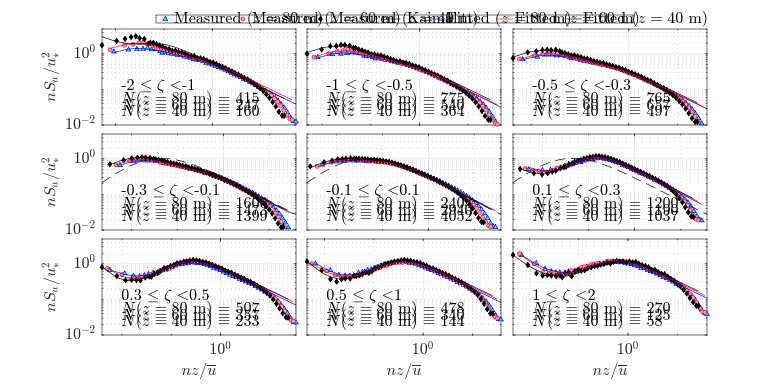

%% SU plot
guess = [200,50,1,1];
clf;close all;
[CoeffU,Su_neutral] = fit_and_plot_spectra(Su,eta,target,minU,Utot,Wind,z,u_star,'u',guess);
set(findall(gcf,'-property','FontSize'), 'FontSize', 12, 'FontName', 'Times')

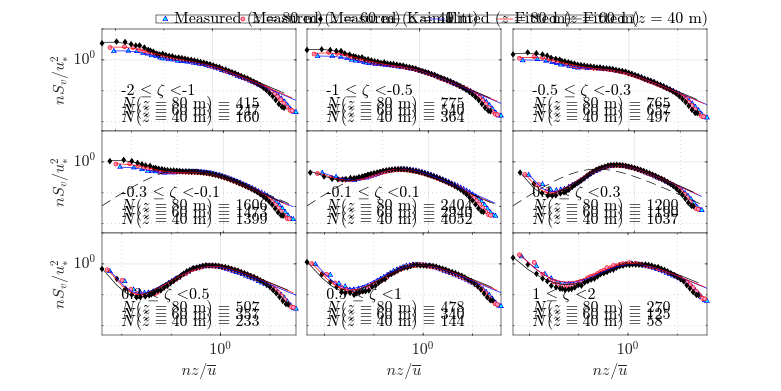

%% SV plot
target = [-2,-1,-0.5,-0.3,-0.1,0.1,0.3,0.5,1,2];
guess = [10,50,10,10];
[CoeffV,Sv_neutral] = fit_and_plot_spectra(Sv,eta,target,minU,Utot,Wind,z,u_star,'v',guess);
set(findall(gcf,'-property','FontSize'), 'FontSize', 12, 'FontName', 'Times')

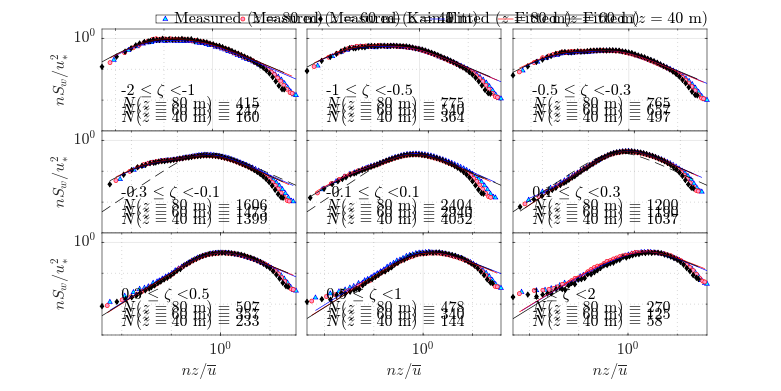

%% SW plot
target = [-2,-1,-0.5,-0.3,-0.1,0.1,0.3,0.5,1,2];
guess = [0.1,10,5,5];
[CoeffW,Sw_neutral] = fit_and_plot_spectra(Sw,eta,target,minU,Utot,Wind,z,u_star,'w',guess);
set(findall(gcf,'-property','FontSize'), 'FontSize', 12, 'FontName', 'Times')

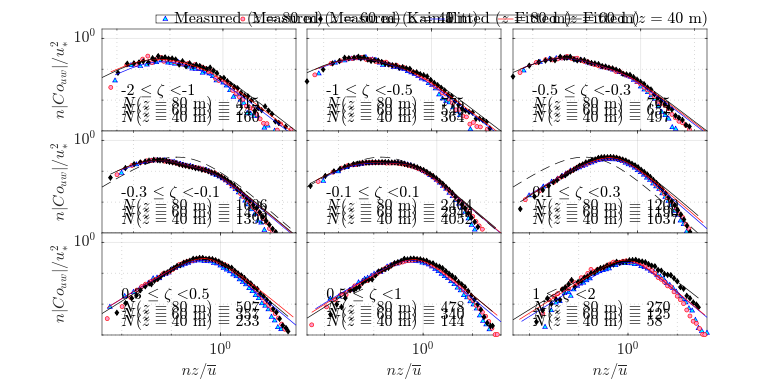

%% SUW plot
guess = [10,10,1,1];
[CoeffUW,Suw_neutral] = fit_and_plot_spectra(-real(Suw),eta,target,minU,Utot,Wind,z,u_star,'uw',guess);
set(findall(gcf,'-property','FontSize'), 'FontSize', 12, 'FontName', 'Times')